% % Save arrays of the x and y coordinates
% x_positions_array = (h.x / 10) + 5.664; % is in cm now
% output_dir = 'D:\Matlab\Matlab output\3D_matrices_surface_height\\';
% output_file_x = fullfile(output_dir, 'x_positions_array_full_plate.mat');
% save(output_file_x, 'x_positions_array');

% y_positions_array = (h.y + 594.001000000000)/10; % is in cm now
% output_dir = 'D:\Matlab\Matlab output\3D_matrices_surface_height\\';
% output_file_y = fullfile(output_dir, 'y_positions_array_full_plate.mat');
% save(output_file_y, 'y_positions_array');

clear  
close all
clc

% Define the specific parameters
rot_rate = 0;  % Rotation rate in rad/s
rot_rate_str = string(rot_rate);
freq_value = 2.2;   % Frequency value
freq_str = string(freq_value);
ampl_value = 7;     % Amplitude in mm
ampl_str = string(ampl_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the surface height data for the specified parameters
surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate_long.mat', rot_rate_str, freq_str, ampl_str)];
data = load(surface_height_file);
surface_height_3D = data.surface_height_3D;
surface_height_3D = permute(surface_height_3D, [2, 1, 3]);  % Swap x and y axes in 3D data

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];
x_data = load(x_positions_file);
y_data = load(y_positions_file);
x_positions = x_data.x_positions_array;
y_positions = y_data.y_positions_array + 2.5;

% Retrieve frame indices from index matrix for the given rotation and amplitude
index_matrix = [
    0, 3, 170, 504;     % Format: 'date', rot_rate, ampl_value, start_frame, end_frame, freq_value
    0, 5, 170, 528;
    0, 7, 170, 528;
    0, 9, 200, 528;
    0.0524, 3, 170, 528;
    0.0524, 5, 170, 576;
    0.0524, 7, 170, 552;
    0.0524, 9, 200, 576;
    0.1047, 3, 170, 528;   
    0.1047, 5, 150, 504;   
    0.1047, 7, 170, 528;   
    0.1047, 9, 170, 576;   
    0.2094, 3, 200, 600;   
    0.2094, 5, 170, 528;  
    0.2094, 7, 170, 576;  
    0.2094, 9, 170, 552;  
    0.4189, 3, 200, 624;
    0.4189, 5, 170, 528;
    0.4189, 7, 170, 575;
    0.4189, 9, 200, 600; 
    0.8378, 3, 170, 600;   
    0.8378, 5, 170, 528;   
    0.8378, 7, 170, 576;  
    0.8378, 9, 170, 552;
];
row = find(index_matrix(:, 1) == rot_rate & index_matrix(:, 2) == ampl_value);
frame_start = index_matrix(row, 3);
frame_last = index_matrix(row, 4);

% Select indices for calculating the RMS
num_frames = 270;  % Default number of frames, adjust if needed
index_end = frame_last - frame_start;
index_begin = index_end - num_frames;
selected_indices = index_begin:index_end;

% Calculate the RMS surface height over the selected frames
oscillations = surface_height_3D(:, :, selected_indices) - mean(surface_height_3D(:, :, selected_indices), 3);
rms_oscillations = rms(oscillations, 3);
amplitude = sqrt(2) * rms_oscillations;
% Create the meshgrid for plotting
[X, Y] = meshgrid(x_positions, y_positions);

% Plot the pcolor plot for RMS values
figure;
pcolor(X, Y, amplitude);
shading flat;
axis equal;
xlabel('x (cm)');
ylabel('y (cm)');
ax = gca;
ylim([2.5 46.0601]);
colorbar;
col = colorbar;
clim([5 9]);
col.Label.FontSize = 10; % Set the font size of the label

ylabel(col, 'Amplitude (mm)');
ax.FontSize = 10;

% Remove extra whitespace around the plot
set(gca, 'LooseInset', max(get(gca, 'TightInset'), 0.08));

% Save the figure in different formats
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\General waves\';
output_file_name = [figures_directory, sprintf('amplitude_from_rms_%sradps_%sHz_%smm', rot_rate_str, freq_str, ampl_str)];

% Save the figure as PNG with tight layout
exportgraphics(gcf, [output_file_name, '.png'], 'Resolution', 300, 'ContentType', 'auto', 'BackgroundColor', 'none');

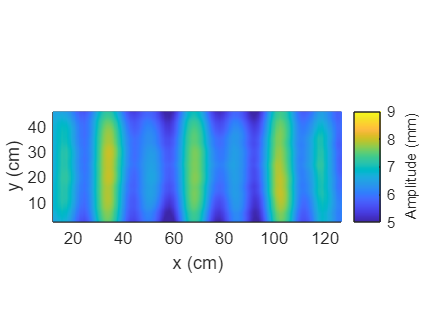

% 
% Save the figure as EPS with tight layout
print(gcf, [output_file_name, '.eps'], '-depsc', '-painters'); % Use -painters for vector graphics

pcolor(amplitude)
shading flat;
colorbar;

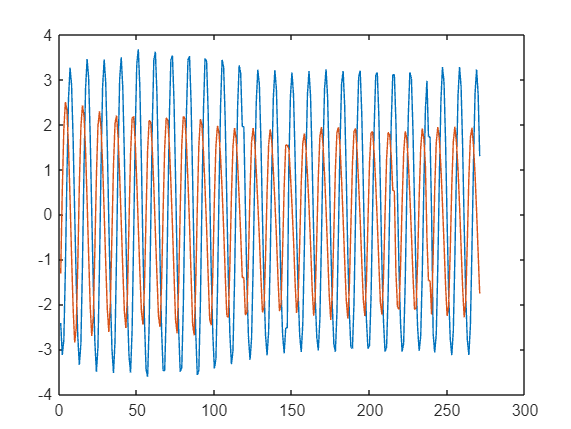

plot(squeeze(oscillations(83,216,:)))
hold on
plot(squeeze(oscillations(83,178,:)))
hold off

% Parameters
Lx = 127/100; % Length of the tank in the x-direction
Ly = 46/100; % Length of the tank in the y-direction
Nx = 436; % Number of spatial points along x
Ny = 166; % Number of spatial points along y
t_tot = 25; % Total time period
f = 2.2; % Frequency
T = 1/f; % Wave period
Nt = 200; % Number of time points
A = 0.007; % Amplitude in meters
g = 9.81

g = 9.8100

lambda = g/(2*pi*f^2)

lambda = 0.3226


k = 2 * pi / lambda; % Wave number
omega = 2 * pi / T; % Angular frequency
phi = pi / 3.8; % Phase shift (adjust as needed)

% Generate spatial and temporal grids
x = linspace(12/100, Lx, Nx); % Spatial points along x
y = linspace(2.5/100, Ly, Ny); % Spatial points along y
t = linspace(0, t_tot, Nt); % Time points
[X, Y, Tgrid] = meshgrid(x, y, t);

% Calculate the theoretical wave
wave1 = A * sin(k * X - omega * Tgrid); % Incident wave
wave2 = 0.1 * A * sin(-k * X - omega * (Tgrid + phi)); % Reflected wave
total_wave = wave1 + wave2; % Superimposed wave

% Calculate the amplitude distribution (RMS over time)
amplitude = sqrt(2) * rms(total_wave, 3); % RMS over time for each (x, y)

% Convert x and y axes to cm for labeling
x_cm = x * 100; % Convert to cm
y_cm = y * 100; % Convert to cm

% Convert amplitude values to mm for colorbar
amplitude_mm = amplitude * 1000; % Convert to mm

% Plot the amplitude distribution
figure;
pcolor(x_cm, y_cm, amplitude_mm); % Pseudocolor plot
shading flat; % Smooth the color transitions
axis equal;
xlabel('x (cm)');
ylabel('y (cm)');
ax = gca;
ax.FontSize = 10;
ylim([2.5 46]);
colorbar;
col = colorbar;
clim([5 9]);
col.Label.FontSize = 10; % Set the font size of the label
ylabel(col, 'Amplitude (mm)');

% Remove extra whitespace around the plot
set(gca, 'LooseInset', max(get(gca, 'TightInset'), 0.08));

% Save the figure in different formats
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\General waves\';
output_file_name = [figures_directory, 'amplitude_from_rms_theoretical'];

% Save the figure as PNG with tight layout
exportgraphics(gcf, [output_file_name, '.png'], 'Resolution', 300, 'ContentType', 'auto', 'BackgroundColor', 'none');

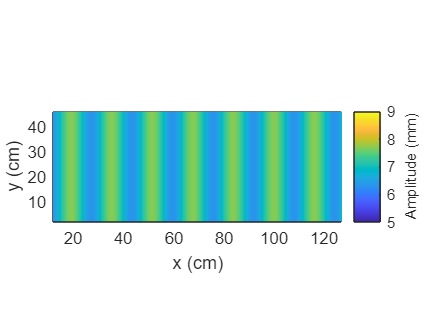

% 
% Save the figure as EPS with tight layout
print(gcf, [output_file_name, '.eps'], '-depsc', '-painters'); % Use -painters for vector graphics

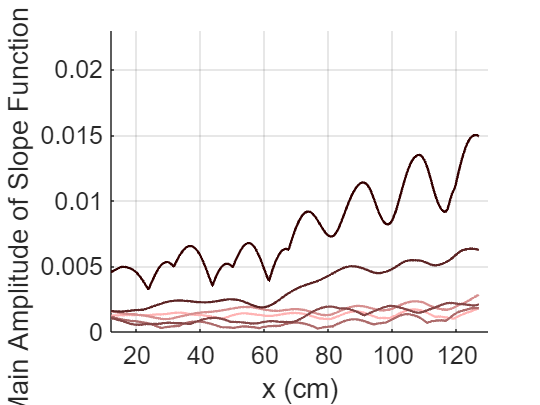

% Clear previous variables and figures
clear 
close all
clc

%date = '09';
freq_value = 2.2; % Frequency value (unchanged)
ampl_value = 3;   % Amplitude value (unchanged)
freq_value = string(freq_value);
ampl_value = string(ampl_value);
frame_rate = 23.98; % frames per second

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Define the array of rotation rates to analyze
rot_rates = [0, 0.0524, 0.1047, 0.2094, 0.4189, 0.8378];
rotation_rates_labels = [0, 0.0083, 0.0167, 0.0333, 0.0667, 0.1333];


% Prepare to plot the main amplitude over x positions for each rot_rate
figure; hold on; % Hold on to plot multiple lines

% Define an array of grey shades (normalized values between 0 and 1)
%grey_shades = linspace(0.7, 0.1, length(rot_rates));

% Define an array of red shades (normalized values for a gradient from dark red to light pink)
num_colors = length(rot_rates); % Number of colors needed
red_shades = linspace(1, 0.2, num_colors); % Light pink to dark red
color_gradient = [red_shades', linspace(0.7, 0, num_colors)', linspace(0.7, 0, num_colors)'];


% Loop over each rotation rate
for r = 1:length(rot_rates)
    rot_rate = rot_rates(r); % Current rotation rate
    rot_rate_str = string(rot_rate);
    
    % Load the surface height data for the current rotation rate
    surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate_str, freq_value, ampl_value)];
    data = load(surface_height_file);
    surface_height_3D = data.surface_height_3D./10; % 3D matrix (x, y, time)

    % Load the x and y coordinate arrays
    x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
    y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

    x_data = load(x_positions_file);
    y_data = load(y_positions_file);

    x_positions = x_data.x_positions_array; % Array of x positions
    y_positions = y_data.y_positions_array; % Array of y positions

    % Get the dimensions of the 3D surface height data
    [num_x, num_y, num_time] = size(surface_height_3D);

    
    % % Time vector: Assuming the time step is uniform and given by the z-dimension
    % T = 1; % Total duration (adjust if needed)
    % dt = T / num_time; % Time step size
    % time_vector = 0:dt:(T-dt); % Time vector

    frame_numbers = 1:num_time;
    time_vector = (frame_numbers - 1) / frame_rate;


    % Initialize an array to store the main amplitude of the slope function at each x location
    amplitude_over_x = zeros(1, num_x);

    % Loop over every x location
    for i = 1:num_x
        % Initialize an array to store the slopes for all time stamps at this x location
        slopes_over_time = zeros(1, num_time);
        
        % Loop over each time stamp
        for t = 1:num_time
            % Get the surface height data at the current x location and time stamp over y-axis
            %surface_height_y = squeeze(surface_height_3D(i, :, t)); % Extract 1D array over y-axis
            surface_height_y = squeeze(surface_height_3D(i, 13:154, t));

            % Perform linear fit (1st-degree polynomial) using polyfit
            %p = polyfit(y_positions, surface_height_y, 1);
            p = polyfit(y_positions(13:154), surface_height_y, 1);
            
            % p(1) is the slope of the fitted line
            slopes_over_time(t) = p(1);
        end
        
        % Perform Fourier transform on the slope function over time
        slope_fft = fft(slopes_over_time);
        
        % Compute the amplitude spectrum
        slope_amplitude = 2 * abs(slope_fft / num_time); % Normalize the amplitude
        slope_amplitude = slope_amplitude(1:floor(num_time/2)); % Take the first half of the FFT (positive frequencies)
        
        % Store the main amplitude (usually the peak of the Fourier transform) for this x position
        [~, max_idx] = max(slope_amplitude); % Find the frequency with the highest amplitude
        amplitude_over_x(i) = slope_amplitude(max_idx); % Store the max amplitude
    end

    % Plot the main amplitude of the slope function over x positions for current rotation rate
    plot(x_positions, amplitude_over_x, 'DisplayName', sprintf('Rot Rate: %.4f Hz', rotation_rates_labels(r)), ...
        'Color', color_gradient(r, :), 'LineWidth', 1.4); % Add color and line width
end

% Add labels, title, and grid to the plot
xlabel('x (cm)');
ylabel('Main Amplitude of Slope Function (cm)');
ylim([0,0.023]);
xlim([12 130])
%title(sprintf('Frequency %sHz %smm', freq_value, ampl_value));
ax = gca;
ax.FontSize = 15;
grid on;
legend show; % Show legend to distinguish different rotation rates
legend('Location','northwest')
hold off; % Release hold

% Save the figure in different formats
% Directory for saving figures
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\Trend\';
file_name = [figures_directory, sprintf('main_amplitude_slope_function_%sHz_%smm_color', freq_value, ampl_value)]; % Combine directory and file name

% Save as a MATLAB figure (.fig)
% saveas(gcf, [file_name, '.fig']); % Save the figure as .fig file
% 
%Save as PNG file
saveas(gcf, [file_name, '.png']); % Save the figure as .png file

% Save as EPS file
print(gcf, [file_name, '.eps'], '-depsc'); % Save the figure as .eps file

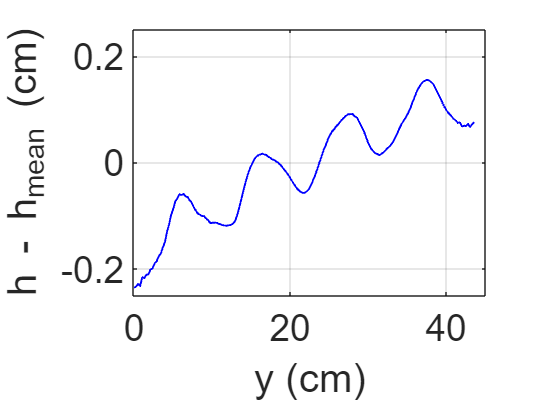

clear 
close all
clc

date = '09';
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
ampl_value = 7;
ampl_value = string(ampl_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the surface height data
surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate, freq_value, ampl_value)];
data = load(surface_height_file);
surface_height_3D = data.surface_height_3D./10; % 3D matrix (x, y, time)

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions


% Choose a specific x position and time step for visualization
x_index = 380;   % Index of x position (choose a number between 1 and length of x_positions)
time_index = 150; % Index of time step (choose a number between 1 and num_time)

% Extract the surface height data at the chosen x position and time step
surface_height_y = squeeze(surface_height_3D(x_index, :, time_index)); % Extract the data along y-axis

% Compute the mean surface height
mean_surface_height = mean(surface_height_y(13:154));

% Subtract the mean to get the fluctuations
fluctuations = surface_height_y - mean_surface_height;

% Plot the surface height as a function of y coordinates
figure;
plot(y_positions, fluctuations, 'b', 'LineWidth', 1);
xlabel('y (cm)');
ylabel('h - h_{mean} (cm)');
%title(sprintf('Surface Height over Y-axis at X Position %d and Time Step %d', x_index, time_index));
ylim([-0.25 0.25]);
xlim([0 45]);
ax = gca;
ax.FontSize = 20;
grid on;

% Save the figure in different formats
% Directory for saving figures
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\Trend\';
file_name = [figures_directory, sprintf('surface_height_over_y_axis_%sradps_%sHz_%smm_x%s_t%s', rot_rate, freq_value, ampl_value, string(x_index), string(time_index))]; % Combine directory and file name

% Save as PNG file
saveas(gcf, [file_name, '.png']); % Save the figure as .png file
print(gcf,'-depsc', fullfile(figures_directory, sprintf('surface_height_over_y_axis_%sradps_%sHz_%smm_x%s_t%s.eps', rot_rate, freq_value, ampl_value, string(x_index), string(time_index))));

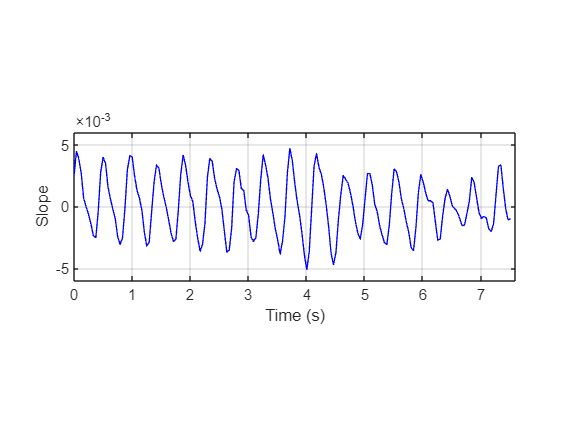

% Clear previous variables and figures
clear 
close all
clc

date = '09';
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
ampl_value = 7;
ampl_value = string(ampl_value);
frame_rate = 23.98; % frames per second


% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the surface height data
surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate, freq_value, ampl_value)];
data = load(surface_height_file);
surface_height_3D = data.surface_height_3D./10; % 3D matrix (x, y, time)

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions

% Get the dimensions of the 3D surface height data
[num_x, num_y, num_time] = size(surface_height_3D);

% Time vector: Assuming the time step is uniform and given by the z-dimension
% Adjust the time step 'dt' and duration 'T' if necessary
% T = 1; % Total duration (adjust if needed)
% dt = T / num_time; % Time step size
% time_vector = 0:dt:(T-dt); % Time vector

frame_numbers = 1:num_time;
time_vector = (frame_numbers - 1) / frame_rate;
dt = time_vector(2) - time_vector(1);

% Choose a specific x position for slope visualization
x_index = 180;   % Index of x position (choose a number between 1 and length of x_positions)

% Initialize an array to store the slopes for all time steps at the chosen x position
slopes_over_time = zeros(1, num_time);

% Loop over each time step to calculate the slope using polyfit
for t = 1:num_time
    % Get the surface height data at the current x position and time stamp over y-axis
    surface_height_y = squeeze(surface_height_3D(x_index, :, t)); % Extract 1D array over y-axis
    
    % Perform linear fit (1st-degree polynomial) using polyfit
    p = polyfit(y_positions, surface_height_y, 1);
    
    % p(1) is the slope of the fitted line
    slopes_over_time(t) = p(1);
end

figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\Trend\';

% Plot the slopes as a function of time
figure; % Create a new figure for slope over time
plot(time_vector, slopes_over_time, 'b', 'LineWidth', 0.8); % Set 'MarkerSize' to a smaller value (e.g., 3)
xlabel('Time (s)');
ylabel('Slope');
ax = gca;
ax.FontSize = 9;
ylim([-6e-3 6e-3]);
xlim([0 7.6]);
%title(sprintf('Slope Over Time at X Position %d', x_index));
grid on;

% Adjust the aspect ratio (e.g., [2 1 1] makes the vertical axis smaller)
pbaspect([3 1 1]); % This sets the ratio of x:y:z to 2:1:1 (horizontal:vertical:depth)

% Save the slope over time figure as a PNG file
slope_file_name = [figures_directory, sprintf('slope_over_time_%sradps_%sHz_%smm_x%s', rot_rate, freq_value, ampl_value, string(x_index))]; % Combine directory and file name for slope
saveas(gcf, [slope_file_name, '.png']); % Save the figure as .png file
print(gcf,'-depsc', fullfile(figures_directory, sprintf('slope_over_time_%sradps_%sHz_%smm_x%s.eps', rot_rate, freq_value, ampl_value, string(x_index))));

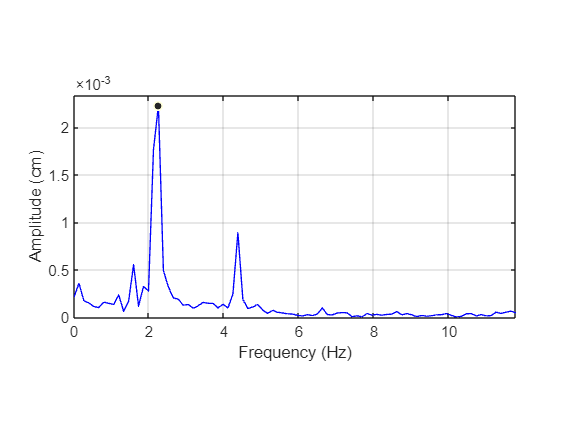


% Close the figure to avoid overlapping
%close(gcf);

% Calculate the Fourier Transform of the slopes
slope_fft = fft(slopes_over_time);
slope_amplitude = 2*abs(slope_fft/ num_time); % Normalize the amplitude
slope_amplitude = slope_amplitude(1:floor(num_time/2)); % Keep only the positive frequencies

% Frequency vector for plotting
frequencies = (0:floor(num_time/2)-1) / (dt * num_time); % New frequency vector based on the new dt

% Plot the Fourier Transform (amplitude spectrum)
figure; % Create a new figure for Fourier Transform
plot(frequencies, slope_amplitude, 'b', 'LineWidth', 0.8);
xlabel('Frequency (Hz)');
ylabel('Amplitude (cm)');
ax = gca;
ax.FontSize = 9;
xlim([0 10])
%title(sprintf('Fourier Transform of Slope Function at X Position %d', x_index));
grid on;
pbaspect([2 1 1]);

% Save the Fourier Transform figure as a PNG file
fourier_file_name = [figures_directory, sprintf('fourier_transform_slope_%sradps_%sHz_%smm_x%s', rot_rate, freq_value, ampl_value, string(x_index))]; % Combine directory and file name for Fourier Transform
saveas(gcf, [fourier_file_name, '.png']); % Save the figure as .png file
print(gcf,'-depsc', fullfile(figures_directory, sprintf('fourier_transform_slope_%sradps_%sHz_%smm_x%s.eps', rot_rate, freq_value, ampl_value, string(x_index))));


% Close the figure to avoid overlapping
%close(gcf);


clear  
close all
clc

% Experimental parameters
ampl_values = [3, 5, 7, 9];  % Amplitude values in mm
rot_rates = [0, 0.0524, 0.1047, 0.2094, 0.4189, 0.8378]; % Rotation rates in rad/s
rotation_rates = [0, 0.0083, 0.0167, 0.0333, 0.0667, 0.1333]; % Your rotation rate values
freq_value = 2.2; % Frequency value (assumed constant in this case)

% Convert frequency to string
freq_value = string(freq_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Initialize matrix to store RMS values for each combination
rms_ranges = zeros(length(rot_rates), length(ampl_values));

% Define index matrix for index_end and index_begin
index_matrix = [
    0, 3, 170, 504;     
    0, 5, 170, 528;
    0, 7, 170, 528;
    0, 9, 200, 528;
    0.0524, 3, 170, 528;
    0.0524, 5, 170, 576;
    0.0524, 7, 170, 552;
    0.0524, 9, 200, 576;
    0.1047, 3, 170, 528;   
    0.1047, 5, 150, 504;   
    0.1047, 7, 170, 528;   
    0.1047, 9, 170, 576;   
    0.2094, 3, 200, 600;   
    0.2094, 5, 170, 528;  
    0.2094, 7, 170, 576;  
    0.2094, 9, 170, 552;   
    0.4189, 3, 200, 624;  
    0.4189, 5, 170, 528;   
    0.4189, 7, 170, 575;  
    0.4189, 9, 200, 600;  
    0.8378, 3, 170, 600;   
    0.8378, 5, 170, 528;   
    0.8378, 7, 170, 576;  
    0.8378, 9, 170, 552;
];

% Define a list of specific cases for additional time frames
special_cases = [
    0.2094, 3;   
    0.2094, 5;  
    0.2094, 7;  
    0.2094, 9;
    0.4189, 3;
    0.4189, 5;   
    0.4189, 7;  
    0.4189, 9;  
    0.8378, 3;   
    0.8378, 5;   
    0.8378, 7;  
    0.8378, 9;
];

% Additional number of frames for special cases
extra_frames = 270 %324; % For example, increase to 85 frames for specific cases

extra_frames = 270


% Loop through each amplitude and rotation rate
for i = 1:length(ampl_values)
    ampl_value = ampl_values(i);
    ampl_str = string(ampl_value); % Convert to string for filename
    
    for j = 1:length(rot_rates)
        rot_rate = rot_rates(j);
        rot_str = string(rot_rate); % Convert to string for filename

        % Check if current (rot_rate, ampl_value) is in special cases
        if any(ismember(special_cases, [rot_rate, ampl_value], 'rows'))
            % Use '_long' suffix and extra frames for special cases
            surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate_long.mat', rot_str, freq_value, ampl_str)];
            num_frames = extra_frames;
        else
            % Use default filename and frames for regular cases
            surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate_long.mat', rot_str, freq_value, ampl_str)];
            num_frames = extra_frames;
        end
        
        % % Load the surface height data
        % surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_str, freq_value, ampl_str)];
        % 
        data = load(surface_height_file);
        surface_height_3D = data.surface_height_3D;

        % Load the x and y coordinate arrays
        x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
        y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

        x_data = load(x_positions_file);
        y_data = load(y_positions_file);

        x_positions = x_data.x_positions_array;
        y_positions = y_data.y_positions_array;

        % Retrieve index_end and index_begin from index_matrix
        row = find(index_matrix(:, 1) == rot_rate & index_matrix(:, 2) == ampl_value);
        frame_last = index_matrix(row, 4);
        frame_start = index_matrix(row, 3);

        % Calculate selected indices based on number of frames
        index_end = frame_last - frame_start;
        index_begin = index_end - num_frames;
        selected_indices = index_begin:index_end;
        
        % % Determine the number of frames to select based on special cases
        % if any(ismember(special_cases, [rot_rate, ampl_value], 'rows'))
        %     % Use additional frames for special cases
        %     index_end = frame_last - frame_start;
        %     index_begin = index_end - extra_frames;
        % else
        %     % Default to 65 frames
        %     index_end = frame_last - frame_start;
        %     index_begin = index_end - 65;
        % end
        % 
        % selected_indices = index_begin:index_end;

        % Compute temporal mean for selected indices
        mean_surface_height = mean(surface_height_3D(:,:,selected_indices), 3);
        % Calculate RMS of surface height deviations from the mean
        rms_surface_height = rms(mean_surface_height(:) - mean(mean_surface_height(:)));
        % Store RMS value in the matrix
        rms_ranges(j, i) = rms_surface_height; 
    end
end

% Convert RMS values to percentages of the corresponding amplitude  
rms_percentages = (rms_ranges ./ ampl_values) * 100;  

% Display the rms_percentages matrix for verification  
disp(rms_percentages);  

    4.9107    2.2870    2.9630    3.2561
    7.4836    2.1255    2.5331    3.9216
    2.7879    3.2101    2.3664    3.5681
    8.1652    4.6342    2.4444    3.7605
    2.6260    2.1536    2.3870    3.7417
    5.1778    3.2137    3.9045    5.7380



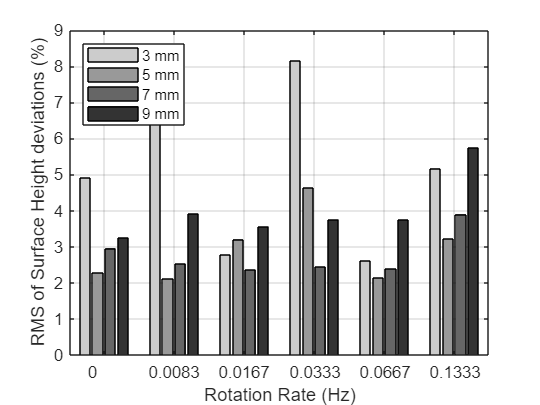


% Plotting the grouped bar chart with percentages  
figure;  
b = bar(rms_percentages);  

% % Display the rms_ranges matrix for verification
% disp(rms_ranges);
% 
% % Plotting the grouped bar chart with filled values from the loop
% figure;
% b = bar(rms_ranges);

% Define grayscale colors for each amplitude (4 levels of gray)
gray_colors = [0.8 0.8 0.8;   % Light gray
               0.6 0.6 0.6;  % Medium gray
               0.4 0.4 0.4;  % Medium-dark gray
               0.2 0.2 0.2];  % Dark gray

% Apply the gray colors to each amplitude group
for k = 1:size(rms_ranges, 2) % Iterate over the number of amplitudes (columns)
    b(k).FaceColor = gray_colors(k, :); % Assign each bar group a gray color
end

% Set plot labels and formatting
xlabel('Rotation Rate (Hz)');
ylabel('RMS of Surface Height deviations (%)');
%ylim([0 0.5])
set(gca, 'XTickLabel', rotation_rates); % Label x-axis with rotation rates
legend({'3 mm', '5 mm', '7 mm', '9 mm'}, 'Location', 'northwest'); % Legend for amplitudes
ax = gca;
ax.FontSize = 10;
grid on;


% Save the figure in different formats
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\';
rms_bar_plot_file_name = [figures_directory, 'bar_plot_rms_surface_height_percentage_270_frames'];

% %Save as PNG file
% saveas(gcf, [rms_bar_plot_file_name, '.png']); % Save the figure as .png file
% 
% % Save as EPS file
% print(gcf, [rms_bar_plot_file_name, '.eps'], '-depsc'); % Save the figure as .eps file


clear  
close all
clc

% Define the specific parameters
rot_rate = 0.2094;  % Rotation rate in rad/s
rot_rate_str = string(rot_rate);
freq_value = 2.2;   % Frequency value
freq_str = string(freq_value);
ampl_value = 3;     % Amplitude in mm
ampl_str = string(ampl_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the surface height data for the specified parameters
surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate_long.mat', rot_rate_str, freq_str, ampl_str)];
data = load(surface_height_file);
surface_height_3D = data.surface_height_3D;
surface_height_3D = permute(surface_height_3D, [2, 1, 3]);  % Swap x and y axes in 3D data

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];
x_data = load(x_positions_file);
y_data = load(y_positions_file);
x_positions = x_data.x_positions_array;
y_positions = y_data.y_positions_array  + 2.5;

% Retrieve frame indices from index matrix for the given rotation and amplitude
index_matrix = [
    0.2094, 3, 200, 600;   
    0.2094, 5, 170, 528;  
    0.2094, 7, 170, 576;  
    0.2094, 9, 170, 552;  
    0.4189, 3, 200, 624;
    0.4189, 5, 170, 528;
    0.4189, 7, 170, 575;
    0.4189, 9, 200, 600; 
    0.8378, 3, 170, 600;   
    0.8378, 5, 170, 528;   
    0.8378, 7, 170, 576;  
    0.8378, 9, 170, 552;
];
row = find(index_matrix(:, 1) == rot_rate & index_matrix(:, 2) == ampl_value);
frame_start = index_matrix(row, 3);
frame_last = index_matrix(row, 4);

% Select indices for calculating the mean
num_frames = 270;  % Default number of frames, adjust if needed
index_end = frame_last - frame_start;
index_begin = index_end - num_frames;
selected_indices = index_begin:index_end;

% Calculate the mean surface height over the selected frames
mean_surface_height = mean(surface_height_3D(:, :, selected_indices), 3);

% Create the meshgrid for plotting
[X, Y] = meshgrid(x_positions, y_positions);

% Plot the pcolor plot
figure;
pcolor(X, Y, mean_surface_height);
shading flat;
axis equal;
xlabel('x (cm)');
ylabel('y (cm)');
ax = gca;
ax.FontSize = 15;
%ylim([0 43.5601]);
ylim([2.5 46.0601]);
colorbar;
col = colorbar;
clim([149, 151]);
col.Ticks = [149, 150, 151];
col.TickLabels = {'14.9','15.0','15.1'};
ylabel(col, 'h (cm)');
ax.FontSize = 15;

% Remove extra whitespace around the plot
set(gca, 'LooseInset', max(get(gca, 'TightInset'), 0.08));


% Save the figure in different formats
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\Average\';
output_file_name = [figures_directory, sprintf('average_surface_height_over_time_%sradps_%sHz_%smm', rot_rate_str, freq_str, ampl_str)];

% Save the figure as PNG with tight layout
exportgraphics(gcf, [output_file_name, '.png'], 'Resolution', 300, 'ContentType', 'auto', 'BackgroundColor', 'none');

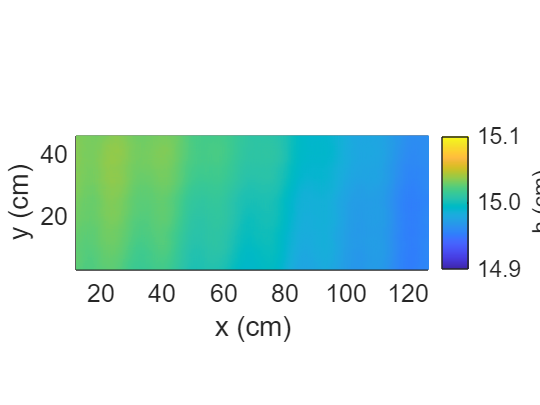


% Save the figure as EPS with tight layout
print(gcf, [output_file_name, '.eps'], '-depsc', '-painters'); % Use -painters for vector graphics

% Step 1: Find the coordinates of the highest (maximum) and lowest (minimum) points
[max_height, max_index] = max(mean_surface_height(:));  % Maximum value and index
%[min_height, min_index] = min(mean_surface_height(:));  % Minimum value and index

% Convert the linear indices to 2D coordinates
[max_row, max_col] = ind2sub(size(mean_surface_height), max_index);
%[min_row, min_col] = ind2sub(size(mean_surface_height), min_index);

% Get the x and y coordinates of these points
x_max = X(max_row, max_col);
y_max = Y(max_row, max_col);
% x_min = X(min_row, min_col);
% y_min = Y(min_row, min_col);
x_min = 71.6641 % manually

x_min = 71.6641

y_min = 18.7441

y_min = 18.7441


fprintf('Maximum height at (x, y): (%.2f, %.2f) cm with height %.2f cm\n', x_max, y_max, max_height);

Maximum height at (x, y): (46.85, 13.20) cm with height 150.55 cm


fprintf('Minimum height at (x, y): (%.2f, %.2f) cm with height %.2f cm\n', x_min, y_min, min_height);

Minimum height at (x, y): (71.66, 18.74) cm with height 148.85 cm


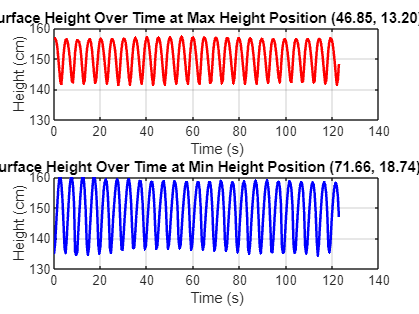


% Step 2: Extract surface height data over time at these coordinates
% We will use max_row, max_col and min_row, min_col to index into the
% surface height data for each time frame (selected_indices).
surface_height_max = squeeze(surface_height_3D(max_row, max_col, selected_indices));
surface_height_min = squeeze(surface_height_3D(min_row, min_col, selected_indices));

% Create a time array based on the number of selected frames
time = (0:length(selected_indices)-1) / freq_value; % Assuming time intervals based on frequency

% Step 3: Plot the surface height over time at maximum and minimum points
figure;
subplot(2, 1, 1);
plot(time, surface_height_max, 'r-', 'LineWidth', 1.5);
title(sprintf('Surface Height Over Time at Max Height Position (%.2f, %.2f) cm', x_max, y_max));
xlabel('Time (s)');
ylabel('Height (cm)');
ylim([130 160]);
grid on;

subplot(2, 1, 2);
plot(time, surface_height_min, 'b-', 'LineWidth', 1.5);
title(sprintf('Surface Height Over Time at Min Height Position (%.2f, %.2f) cm', x_min, y_min));
xlabel('Time (s)');
ylabel('Height (cm)');
ylim([130 160]);
grid on;


% Save the plot of surface height over time at max and min points
output_time_series_file_name = [figures_directory, sprintf('surface_height_time_series_%sradps_%sHz_%smm', rot_rate_str, freq_str, ampl_str)];
% exportgraphics(gcf, [output_time_series_file_name, '.png'], 'Resolution', 300, 'ContentType', 'auto', 'BackgroundColor', 'none');
% print(gcf, [output_time_series_file_name, '.eps'], '-depsc', '-painters');


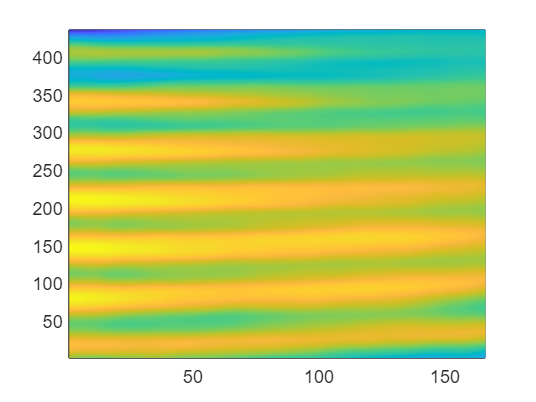

pcolor(mean_surface_height)
shading flat

pcolor

% To plot the average surface height

clear 
close all
clc

date = '09';
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
ampl_value = 7;
ampl_value = string(ampl_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the surface height data
surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate, freq_value, ampl_value)];
data = load(surface_height_file);
surface_height_3D = data.surface_height_3D;

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array;
y_positions = y_data.y_positions_array;

index_end = 350 - 170 %575 - 170

index_end = 180

index_begin = index_end - 108 %324 

index_begin = 72


% Determine the range of time steps or indices for the RMS calculation
selected_indices = index_begin:index_end; % Modify this to your desired range of indices

% 1: Compute temporal mean
mean_surface_height = mean(surface_height_3D(:,:,selected_indices), 3);

rms_surface_height = rms(mean_surface_height(:) - mean(mean_surface_height(:)))

rms_surface_height = 0.1862



% % Step 1: Square the surface height values over the selected time steps
% squared_surface_height = surface_height_3D(:,:,selected_indices).^2;
% 
% 
% % Step 2: Calculate the mean of the squared values over the time steps (3rd dimension)
% mean_squared_surface_height = mean(squared_surface_height, 3);
% 
% % Step 3: Take the square root of the mean squared values to get the RMS
% rms_surface_height = sqrt(mean_squared_surface_height);
% 
% % Optional: Transpose to match the orientation of x and y positions if needed
% rms_surface_height = rms_surface_height';
%rms_surface_height = rms_surface_height./10;


% Find the minimum and maximum values of the RMS surface height
min_rms_value = min(rms_surface_height(:)); % Minimum value in the matrix
max_rms_value = max(rms_surface_height(:)); % Maximum value in the matrix

% Determine the range
rms_range = max_rms_value - min_rms_value;


% Display the results
fprintf('%.4f\n', min_rms_value);

14.9525


fprintf('%.4f\n', max_rms_value);

15.0346


fprintf('%.4f\n', rms_range);

0.0821



% Using percentiles:
lower_percentile = prctile(rms_surface_height(:), 5);  % 5th percentile
upper_percentile = prctile(rms_surface_height(:), 95); % 95th percentile
robust_range = upper_percentile - lower_percentile;

fprintf('%.4f\n', robust_range);

0.0625


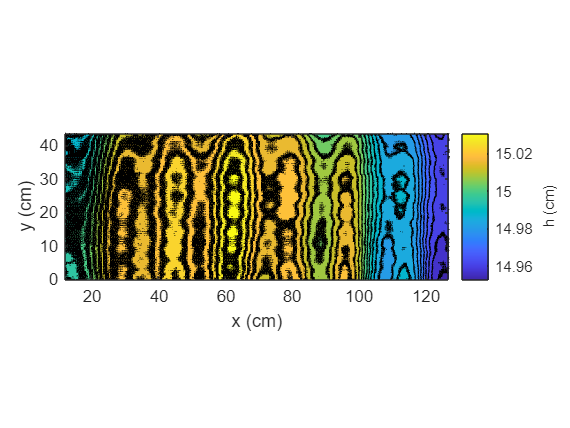



[X, Y] = meshgrid(x_positions, y_positions);

% Plot the RMS surface height as a filled contour plot
figure;
contourf(X, Y, rms_surface_height, 20); % 20 contour levels
axis equal
xlabel('x (cm)');
ylabel('y (cm)');
ax = gca; % Get current axes
ax.FontSize = 10;
%title('Contour Plot of RMS Surface Height Over Time');
colorbar; % Display color scale
col = colorbar;
ylabel(col, 'h (cm)');
ax.FontSize = 10;


% Save the RMS figure in different formats
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\';
rms_file_name = [figures_directory, sprintf('rms_surface_height_over_time_%sradps_%sHz_%smm',rot_rate,freq_value,ampl_value)]; % Combine directory and file name

% Save as PNG file
saveas(gcf, [rms_file_name, '.png']); % Save the figure as .png file
exportgraphics(gcf, fullfile(figures_directory, sprintf('rms_surface_height_over_time_%sradps_%sHz_%smm.eps',rot_rate,freq_value,ampl_value)), 'ContentType', 'vector', 'BackgroundColor', 'none');

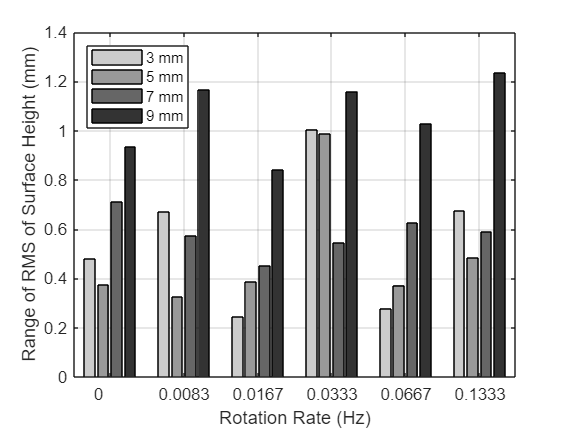

% Sample data: rows for rotation rates, columns for amplitudes (4 amplitudes per rate)
rms_ranges = [...];

% Define rotation rates and amplitudes
rotation_rates = [0, 0.0083, 0.0167, 0.0333, 0.0667, 0.1333]; % Your rotation rate values
amplitudes = {'3 mm', '5 mm', '7 mm', '9 mm'}; % Labels for amplitudes

% Create grouped bar plot
figure;
b = bar(rms_ranges);

% Define grayscale colors for each amplitude (4 levels of gray)
gray_colors = [0.8 0.8 0.8;   % Light gray
               0.6 0.6 0.6;  % Medium gray
               0.4 0.4 0.4;  % Medium-dark gray
               0.2 0.2 0.2];  % Dark gray
              
% Apply the gray colors to each amplitude group
for k = 1:size(rms_ranges, 2) % Iterate over the number of amplitudes (columns)
    b(k).FaceColor = gray_colors(k, :); % Assign each bar group a gray color
end

xlabel('Rotation Rate (Hz)');
ylabel('Range of RMS of Surface Height (mm)');
%title('Range of RMS Surface Heights for Different Rotation Rates and Amplitudes');
set(gca, 'XTickLabel', rotation_rates); % Label x-axis with rotation rates
legend(amplitudes); % Legend for amplitudes
legend('Location','northwest')
ax.FontSize = 10;

% Save the figure in different formats
% Directory for saving figures
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\';
rms_bar_plot_file_name = [figures_directory, 'bar_plot_range_rms_surface_height'];

%Save as PNG file
saveas(gcf, [rms_bar_plot_file_name, '.png']); % Save the figure as .png file

% Save as EPS file
print(gcf, [rms_bar_plot_file_name, '.eps'], '-depsc'); % Save the figure as .eps file

grid on;

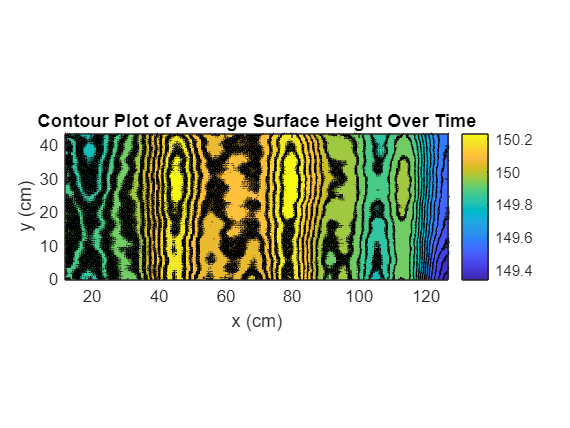

% Average surface height, not RMS

% Specify the range of time steps or 3rd dimension you want to average
selected_indices = index_begin:index_end; % Modify this to your desired range of indices

% Calculate the average surface height over the selected time steps (3rd dimension)
average_surface_height = mean(surface_height_3D(:,:,selected_indices), 3); % Averaging only over the selected range
average_surface_height = average_surface_height';

% % Calculate the average surface height over time (3rd dimension)
% average_surface_height = mean(surface_height_3D, 3);
% average_surface_height = average_surface_height';

% Create a meshgrid using the x and y positions (ensure dimensions match)
[X, Y] = meshgrid(x_positions, y_positions);

% Create a filled contour plot of the average surface height
figure;
contourf(X, Y, average_surface_height, 20); % 20 contour levels
axis equal
xlabel('x (cm)');
ylabel('y (cm)');
ax = gca; % Get current axes
ax.FontSize = 10;
title('Contour Plot of Average Surface Height Over Time');
colorbar; % Display color scale


% Save the figure in different formats
% Directory for saving figures
figures_directory = 'D:\Matlab\Matlab output\3D_matrices_surface_height\Figures\';
file_name = [figures_directory, 'average_surface_height_over_time']; % Combine directory and file name

% Save as PNG file
saveas(gcf, [file_name, '.png']); % Save the figure as .png file
exportgraphics(gcf, fullfile(figures_directory, sprintf('average_surface_height_over_time_%sradps_%sHz_%smm.eps',rot_rate,freq_value,ampl_value), 'ContentType', 'image', 'BackgroundColor', 'none');


% % Start timing
% tic;
% 
% clear;
% close all;
% clc;
% 
% % Define the input parameters for each combination of date, rot_rate, ampl_value, and corresponding start and end frames
% input_parameters = {
%     '10', 0, 3, 170, 350;     % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
%     '10', 0, 5, 170, 350;
%     '10', 0, 7, 170, 325;
%     '10', 0, 9, 200, 350;
%     '10', 0.0524, 3, 170, 300;
%     '10', 0.0524, 5, 170, 300;
%     '10', 0.0524, 7, 170, 300;
%     '10', 0.0524, 9, 200, 350;
%     '09', 0.1047, 3, 170, 375;   
%     '09', 0.1047, 5, 150, 300;   
%     '09', 0.1047, 7, 170, 350;   
%     '09', 0.1047, 9, 170, 350;   
%     '10', 0.2094, 3, 200, 400;   
%     '10', 0.2094, 5, 170, 300;  
%     '10', 0.2094, 7, 170, 350;  
%     '10', 0.2094, 9, 170, 300;   
%     '09', 0.4189, 3, 200, 400;  
%     '09', 0.4189, 5, 170, 350;   
%     '09', 0.4189, 7, 170, 350;  
%     '09', 0.4189, 9, 200, 350;  
%     '09', 0.8378, 3, 170, 350;   
%     '09', 0.8378, 5, 170, 350;   
%     '09', 0.8378, 7, 170, 350;  
%     '09', 0.8378, 9, 170, 300;   
% };
% %% Define frequency value (assuming it stays constant)
% freq_value = 2.2;
% freq_value = string(freq_value);
% selected_long_axis_point = 170;  % Point on long axis to monitor over time
% frame_rate = 23.98;  % Frame rate in frames per second
% 
% % Initialize a table to store results
% results = table('Size', [0 5], 'VariableTypes', {'string', 'double', 'double', 'double', 'double'}, ...
%                 'VariableNames', {'Date', 'RotRate', 'AmplValue', 'RMS_Amplitude', 'Standard_Error'});
% 
% % Loop through all the input parameter combinations
% for i = 1:size(input_parameters, 1)
%     date = input_parameters{i, 1};
%     rot_rate = input_parameters{i, 2};
%     ampl_value = input_parameters{i, 3};
%     start_frame = input_parameters{i, 4};
%     end_frame = input_parameters{i, 5};
% 
%     % Define the base directory for input and output files
%     input_dir = sprintf('D:\\Matlab\\Matlab input\\202409%s_full_plate_final\\202409%s_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', ...
%                         date, date, string(rot_rate), freq_value, string(ampl_value));
% 
%     % Define the base file name and extension
%     base_file_name = sprintf('202409%s_%sradps_%sHz_%smm_full_plate_frame_', date, string(rot_rate), string(freq_value), string(ampl_value));
%     file_extension = 'A_vel_new.dat';
% 
%     % Initialize array to store slopes for each frame
%     slopes_over_time = zeros(end_frame - start_frame + 1, 1);
% 
%     % Iterate over each frame to calculate the slope for the selected long axis point
%     for frame_num = start_frame:end_frame
%         % Construct the file name for the current frame
%         frame_str = sprintf('%04d', frame_num);
%         file_name = [base_file_name, frame_str, file_extension];
%         input_file = fullfile(input_dir, file_name);
% 
%         % Load the data
%         dr = loadvec(input_file);
% 
%         % Process the data: remove rows and columns with only zeros
%         dr_new = dr;
%         dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
%         dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
%         dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
%         dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
%         dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
%         dr_new.vy(all(dr_new.vy == 0, 2), :) = [];
% 
%         % Compute the surface height
%         h_0 = 150; % surface-pattern distance in mm
%         h = surfheight(dr_new, h_0);
%         surface_height = h.w;
% 
%         % Surface height on short axis for the selected long axis point
%         surf_height_short_axis = surface_height(selected_long_axis_point, :);
%         ampl_short_axis = surf_height_short_axis;
%         values_short_axis = h.y / 10;  % Convert to cm
% 
%         % Linear fit for slope calculation
%         p = polyfit(values_short_axis, ampl_short_axis, 1);  
%         slopes_over_time(frame_num - start_frame + 1) = p(1);  % Store the slope
%     end
% 
%     % Calculate RMS amplitude and standard error for this combination
%     rms_amplitude = sqrt(mean(slopes_over_time.^2));  % RMS amplitude
%     standard_error = std(slopes_over_time) / sqrt(length(slopes_over_time));  % Standard error
% 
%     % Store the results in the table
%     new_row = {date, rot_rate, ampl_value, rms_amplitude, standard_error};
%     results = [results; new_row];
% end
% 
% % Save the table to a CSV file
% output_dir = 'D:\Matlab\Matlab output\RMS_Results\';  % Desired folder for saving
% if ~exist(output_dir, 'dir')
%    mkdir(output_dir);
% end
% 
% output_file = fullfile(output_dir, 'RMS_Amplitude_and_Standard_Error_Results_Full.csv');
% writetable(results, output_file);
% 
% toc;

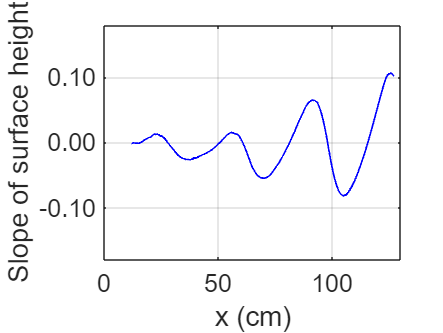

%% Script 1: Slope Across Long Axis for a Specific Frame
tic;

clear 
close all
clc

%% Parameters
date = '09';
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
ampl_value = 7;

% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\202409%s_full_plate_final\\202409%s_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', date, date, rot_rate, freq_value, string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\202409%s_full_plate_final_results\\202409%s_%sradps_%sHz_%smm_full_plate\\Trend\\', date, date, rot_rate, freq_value, string(ampl_value));

% Define the base file name and extension
base_file_name = sprintf('202409%s_%sradps_%sHz_%smm_full_plate_frame_', date, rot_rate, freq_value, string(ampl_value));
file_extension = 'A_vel_new.dat';

%% Parameters specific to 'long_axis' mode
frame_num = 280;  % Frame number for slope calculation across long axis

%% Construct the file name for the specified frame
frame_str = sprintf('%04d', frame_num);
file_name = [base_file_name, frame_str, file_extension];
input_file = fullfile(input_dir, file_name);

%% Load the data
dr = loadvec(input_file);

%% Process the data: remove rows and columns with only zeros
dr_new = dr;
dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

%% Compute the surface height
h_0 = 150; % Surface-pattern distance in mm
h = surfheight(dr_new, h_0);
surface_height = h.w;

%% Initialize array to store slopes along the long axis
num_long_axis_points = size(surface_height, 1);
slopes = zeros(num_long_axis_points, 1);

%% Calculate slopes along the short axis for each long axis point
for i = 1:num_long_axis_points
    surf_height_short_axis = surface_height(i, :);
    ampl_short_axis = surf_height_short_axis;
    values_short_axis = h.y / 10;  % Convert to cm

    % Linear fit for slope calculation
    p = polyfit(values_short_axis, ampl_short_axis, 1);  
    slopes(i) = p(1);  % Store the slope
end

%% Plot slopes over long axis points
values_long_axis = (h.x / 10) + 5.664;  % Convert to cm
plot(values_long_axis, slopes, 'b', 'LineWidth', 1);
%title(sprintf('Slope over long axis for frame %d', frame_num));
ax = gca; % Get current axes
ax.YAxis.TickLabelFormat = '%.2f'; % Display numbers in decimal format with 3 decimal places
xlim([0,130])
ylim([-0.18,0.18])
xlabel('x (cm)');
ylabel('Slope of surface height');
ax.FontSize = 15;
grid on;




%% Save the plot
%print(gcf, '-depsc', fullfile(output_dir, sprintf('202409%s_%sradps_%sHz_%smm_slope_vs_long_axis_%s.eps', date, rot_rate, freq_value, string(ampl_value), string(frame_num))));
%saveas(gcf, fullfile(output_dir, sprintf('202409%s_%sradps_%sHz_%smm_slope_vs_long_axis_%s.png', date, rot_rate, freq_value, string(ampl_value), string(frame_num))));

toc;

Elapsed time is 4.011889 seconds.


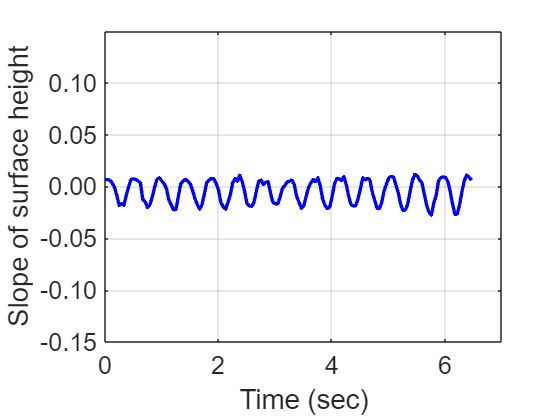

%% Script 2: Slope Over Time at a Specific Long Axis Point
tic;

clear 
close all
clc

%% Parameters
date = '10';
rot_rate = 0;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
ampl_value = 7;

% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\202409%s_full_plate_final\\202409%s_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', date, date, rot_rate, freq_value, string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\202409%s_full_plate_final_results\\202409%s_%sradps_%sHz_%smm_full_plate\\Trend\\', date, date, rot_rate, freq_value, string(ampl_value));

% Define the base file name and extension
base_file_name = sprintf('202409%s_%sradps_%sHz_%smm_full_plate_frame_', date, rot_rate, freq_value, string(ampl_value));
file_extension = 'A_vel_new.dat';

%% Parameters specific to 'time' mode
selected_long_axis_point = 170;  % Point on long axis to monitor over time
start_frame = 170;  % Start frame number
end_frame = 325;    % End frame number
frame_rate = 23.98;  % Frame rate in frames per second

%% Initialize array to store slopes for each frame
slopes_over_time = zeros(end_frame - start_frame + 1, 1);

%% Calculate time in seconds for each frame
% frame_numbers = start_frame:end_frame;
% time_in_seconds = (frame_numbers - 1) / frame_rate;
frame_numbers = 1:156;
time_in_seconds = (frame_numbers - 1) / frame_rate;

%% Iterate over each frame to calculate the slope for the selected long axis point
for frame_num = start_frame:end_frame
    % Construct the file name for the current frame
    frame_str = sprintf('%04d', frame_num);
    file_name = [base_file_name, frame_str, file_extension];
    input_file = fullfile(input_dir, file_name);

    % Load the data
    dr = loadvec(input_file);

    % Process the data: remove rows and columns with only zeros
    dr_new = dr;
    dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
    dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
    dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
    dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

    % Compute the surface height
    h_0 = 150; % Surface-pattern distance in mm
    h = surfheight(dr_new, h_0);
    surface_height = h.w;

    % Surface height on short axis for the selected long axis point
    surf_height_short_axis = surface_height(selected_long_axis_point, :);
    ampl_short_axis = surf_height_short_axis;
    values_short_axis = h.y / 10;  % Convert to cm

    % Linear fit for slope calculation
    p = polyfit(values_short_axis, ampl_short_axis, 1);  
    slopes_over_time(frame_num - start_frame + 1) = p(1);  % Store the slope
end

%% Plot slopes over time (in seconds)
plot(time_in_seconds, slopes_over_time, 'b', 'LineWidth', 2);
%title(sprintf('Slope of surface height %sradps %sHz %smm pos %d', rot_rate, freq_value, string(ampl_value), selected_long_axis_point));
xlabel('Time (sec)');
ylabel('Slope of surface height');
ax = gca; % Get current axes
ax.YAxis.TickLabelFormat = '%.2f'; % Display numbers in decimal format with 3 decimal places
xlim([0,7])
ylim([-0.15,0.15])
ax.FontSize = 15;
grid on;

% %% Compute Peak-to-Peak Amplitude
% max_slope = max(slopes_over_time);  % Maximum slope value
% min_slope = min(slopes_over_time);  % Minimum slope value
% peak_to_peak_amplitude = max_slope - min_slope;
% fprintf('Peak-to-Peak Amplitude: %.4f\n', peak_to_peak_amplitude);
% 
% %% Compute RMS Amplitude
% rms_amplitude = rms(slopes_over_time);  % Root Mean Square of the slopes
% %% Compute Standard Deviation of Slopes
% slope_std_dev = std(slopes_over_time);  % Standard deviation of slope values
% 
% %% Compute Standard Error of RMS (SERMS)
% N = length(slopes_over_time);  % Number of frames
% serms = slope_std_dev / sqrt(N);  % Standard error of the RMS amplitude
% 
% %% Display the values
% fprintf('RMS Amplitude: %.4f\n', rms_amplitude);
% fprintf('Standard Deviation of Slopes: %.4f\n', slope_std_dev);
% fprintf('Standard Error of RMS Amplitude (SERMS): %.4f\n', serms);

%% Save the plot
print(gcf,'-depsc', fullfile(output_dir, sprintf('%sradps_%sHz_%smm_pos_%d_slope_over_time.eps', rot_rate, freq_value, string(ampl_value), selected_long_axis_point)));
saveas(gcf, fullfile(output_dir, sprintf('%sradps_%sHz_%smm_pos_%d_slope_over_time.png', rot_rate, freq_value, string(ampl_value), selected_long_axis_point)));


toc;

Elapsed time is 561.268459 seconds.


% To plot the average slope (averaged out over time/all the frames) as a
% function of the long axis location

tic;

clear 
close all
clc

%% Parameters
ampl_value = 7;
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);

% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\20240909_full_plate_final\\20240909_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', rot_rate, freq_value, string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\20240909_full_plate_final_results\\20240909_%sradps_%sHz_%smm_full_plate\\Trend\\', rot_rate, freq_value, string(ampl_value));

% Define the base file name and extension
base_file_name = sprintf('20240909_%sradps_%sHz_%smm_full_plate_frame_', rot_rate, freq_value, string(ampl_value));
file_extension = 'A_vel_new.dat';

%% Common Parameters
start_frame = 190;  % Start of frame number for time mode
end_frame = 350;  % End of frame number for time mode
frame_rate = 23.98;  % Frame rate in frames per second

%% Initialize for Averaging Slopes Over Time
% First, we'll compute the slopes for each frame and each long axis point
% Then, we'll average them over time
first_frame_str = sprintf('%04d', start_frame);
first_file_name = [base_file_name, first_frame_str, file_extension];
first_input_file = fullfile(input_dir, first_file_name);

% Load the first frame data to get the dimensions
dr_first = loadvec(first_input_file);
dr_first.x(:, all(dr_first.vy == 0, 2)) = [];
dr_first.y(:, all(dr_first.vy == 0, 1)) = [];
dr_first.vx(:, all(dr_first.vx == 0, 1)) = [];
dr_first.vx(all(dr_first.vx == 0, 2), :) = [];
dr_first.vy(:, all(dr_first.vy == 0, 1)) = [];
dr_first.vy(all(dr_first.vy == 0, 2), :) = [];

% Compute the surface height for the first frame to get the size
h_0 = 150; % surface-pattern distance in mm
h_first = surfheight(dr_first, h_0);
surface_height_first = h_first.w;

% Number of points along the long axis and short axis
num_long_axis_points = size(surface_height_first, 1);
num_short_axis_points = size(surface_height_first, 2);

% Initialize a matrix to accumulate the slopes for each point along the long axis
slope_accumulator = zeros(num_long_axis_points, end_frame - start_frame + 1);

%% Iterate over frames to calculate slopes for each long axis point
for frame_num = start_frame:end_frame
    % Construct the file name for the current frame
    frame_str = sprintf('%04d', frame_num);
    file_name = [base_file_name, frame_str, file_extension];
    input_file = fullfile(input_dir, file_name);

    % Load the data for the current frame
    dr = loadvec(input_file);

    % Process the data: remove rows and columns with only zeros
    dr.x(:, all(dr.vy == 0, 2)) = [];
    dr.y(:, all(dr.vy == 0, 1)) = [];
    dr.vx(:, all(dr.vx == 0, 1)) = [];
    dr.vx(all(dr.vx == 0, 2), :) = [];
    dr.vy(:, all(dr.vy == 0, 1)) = [];
    dr.vy(all(dr.vy == 0, 2), :) = [];

    % Compute the surface height for this frame
    h = surfheight(dr, h_0);
    surface_height = h.w;

    % Calculate the slope along the short axis for each long axis point
    for i = 1:num_long_axis_points
        surf_height_short_axis = surface_height(i, :);
        ampl_short_axis = surf_height_short_axis;
        values_short_axis = h.y / 10;  % Convert to cm
        
        % Linear fit for slope calculation
        p = polyfit(values_short_axis, ampl_short_axis, 1);  
        slope_accumulator(i, frame_num - start_frame + 1) = p(1);  % Store the slope for this frame
    end
end

%% Calculate the average slope over time for each long axis point
average_slope = mean(slope_accumulator, 2);

%% Plot the average slope over the long axis
values_long_axis = h.x / 10;  % Convert to cm
plot(values_long_axis, average_slope, 'b', 'LineWidth', 2);
title('Average Slope over Long Axis (Averaged over Time)');
xlabel('Position on Long Axis (cm)');
ylabel('Average Slope of Surface Height');
grid on;

% Save the plot
saveas(gcf, fullfile(output_dir, sprintf('average_%d_to_%d_slope_vs_long_axis.png',start_frame,end_frame)));

toc;

% % Surface height on short axis
% % Plot the amplitude/surface height over the short axis
% surf_height_short_axis = surface_height(170,:);
% ampl_short_axis = surf_height_short_axis;
% values_short_axis = h.y/10; % in cm
% plot(values_short_axis,surf_height_short_axis)
% title('Surface height over short axis')
% xlabel('Position on short axis (cm)')
% ylabel('Surface height (mm)')
% 
% p = polyfit(values_short_axis, ampl_short_axis, 1);  % Degree 1 for a linear trend
% trendline = polyval(p, values_short_axis);           % Compute the trendline
% plot(values_short_axis, ampl_short_axis, 'b');       % Plot original data
% hold on;
% plot(values_short_axis, trendline, 'r', 'LineWidth', 2);  % Plot the trendline
% hold off;
% slope = p(1)



% output_file_png_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% exportgraphics(gcf, output_file_png_surf_height_short);
% output_file_fig_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% savefig(gcf, output_file_fig_surf_height_short);

